% change directory in order for relative references to work
cd(fileparts(matlab.desktop.editor.getActiveFilename))

# Deep learning

## Working with images

Image classification can be done with convolutional neural networks (CNN). Before going into detail let's go over some basics and illustrate some concepts. You are familiar with the concept of convolution from the course on signals:

$(f*g)(t)=\int _{-\infty }^{\infty }f(\tau )g(t-\tau )\,d\tau \;\text{(continuous)}$ or $(f*g)[n]=\sum _{m=-\infty }^{\infty }f[m]g[n-m] \ \text{(discrete)}$

In the above expressions the function $g(t)$ can be seen a filter being applied to $f(t)$. The weights of a CNN correspond with the properties of the filters that are being used. Given enough data you will be able to find the optimal values of these filters by training the network (i.e. the filters are learned from the data). 

The application of a filter on data leads to what is called a feature map.

### convolution (1D)

The definition of a convolution of a vector $u \in \mathbb{R}^{m\times1}$ and a vector $v \in \mathbb{R}^{n\times1}$ is given by:


$$w(k) = \sum_j u(j)v(k-j+1)\text{ where } j= \max \{1, k+1-n\}:1:\min \{ k,m\}$$


There are different ways of applying the filter to the input sequence. This will change the shape of the resulting feature map. A one dimensional example is shown below

u = [3 0 0 1 1 0 0 1 1 10]; % data
v = [0 2 1];                % filter

% w(1):
% j = 1:1:1
% => w(1) = u(1)*v(1) = 0
% w(2):
% j = 1:1:2
% => w(2) = u(1)*v(2)+u(2)*v(1) = 6
% w(11):
% j = 9:1:10
% => w(11) = u(9)*v(3) + u(10)*v(2) = 21

conv(u,v) % total convolution (m + n - 1)

ans =      0     6     3     0     2     3     1     0     2     3    21    10


conv(u,v,'same') % same output size

ans =      6     3     0     2     3     1     0     2     3    21


conv(u,v,'valid')

ans =      3     0     2     3     1     0     2     3


The option "valid" is selected this means that the convolution will only be done for the locations in our data where the filter actually fits.

### convolution (2D)

The definition of a convolution of a matrix $A$ and a matrix $B$ is given by:

$C(j,k) = \sum_p\sum_qA(p,q)B(j-p+1,k-q+1)$ , where $p$ and $q$ run over all values that lead to legal subscripts of $A(p,q)$ and $B(j-p+1,k-q+1)$.

The result of convolving the data with our filter is shown below. 

d = [1 1 1 0 0;
     0 1 1 1 0;
     0 0 1 1 1;
     0 0 1 1 0;
     0 1 1 0 0];
f = [1 1 1;
     0 0 1;
     0 0 1];
C = conv2(d,f)

C =      1     2     3     2     1     0     0
     0     1     3     4     3     1     0
     0     0     2     4     5     3     1
     0     0     1     3     4     3     1
     0     1     2     2     3     2     1
     0     0     0     1     2     1     0
     0     0     0     1     1     0     0


conv2(d,f,"valid")

ans =      2     4     5
     1     3     4
     2     2     3


### Illustrations

Let's illustrate the affect of a couple of filters on an image. Note that a standard color image has 3 channels, one for red, blue and green. For this application we flatten the channels into one by averageing the values.

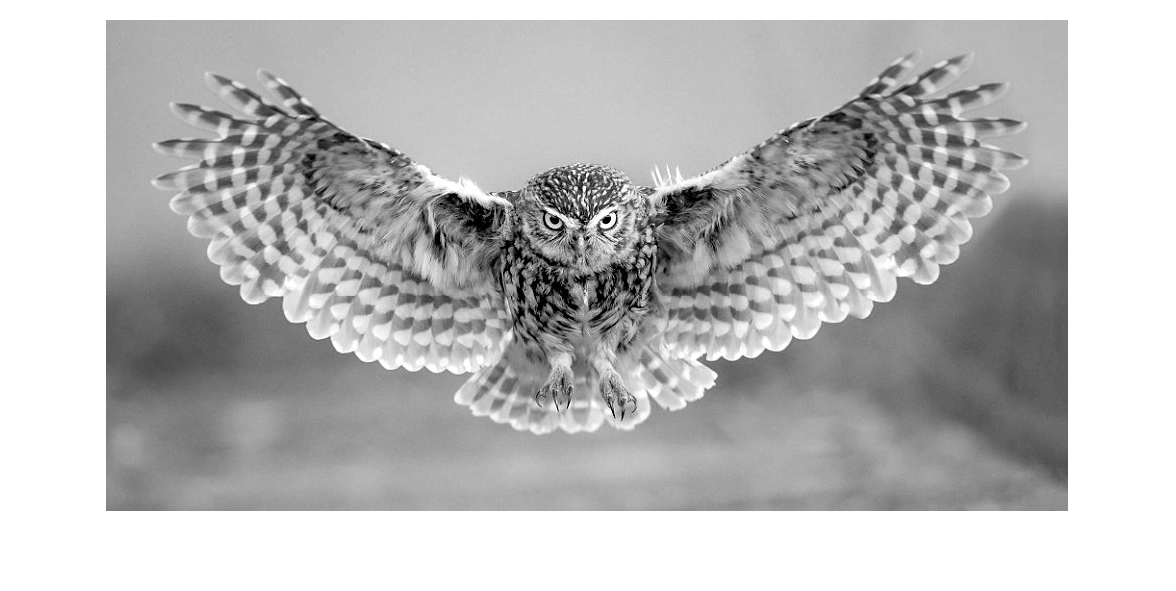

% Load single image as matrix
I = mean(imread("img/owl.jpg"),3);
figure
imshow(I,[0, 255])

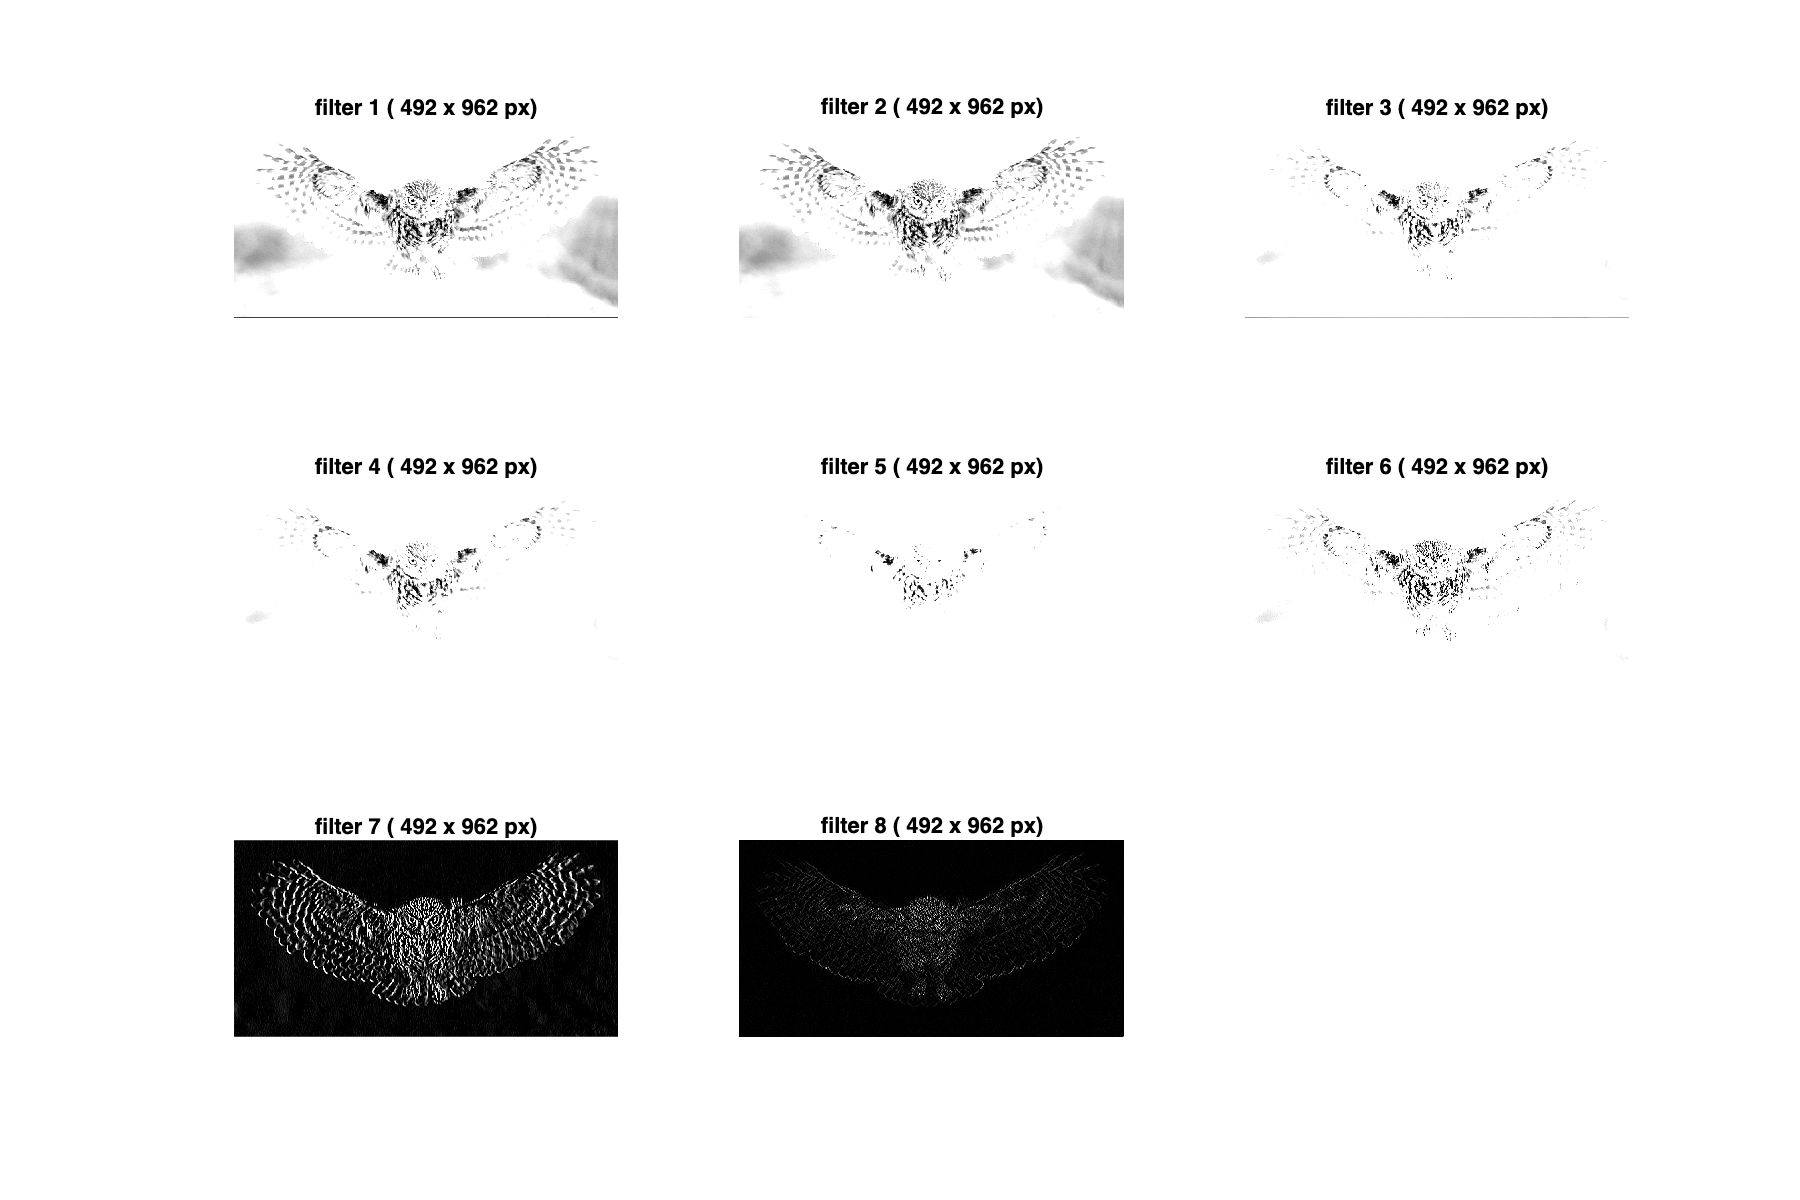

% effect of a set of simple filters on the image:
f = {[1 1;0 0], ...
     [0 0;1 1], ...
     [0 1 1; 0 1 0], ...
     [1 0 0; 0 1 0; 0 0 1], ...
     [1/2 1 1/2;1/2 1 1/2;1 0 1],...
     [3 -1 0; 3 -2 0],...
     [1 1 -1 -1; 1 1 -1 -1;1 1 -1 -1;1 1 -1 -1],...
     [1 1 -1 -1; -1 -1 1 1;1 1 -1 -1;-1 -1 1 1]};
figure('Position', [0 0 900 600])
psize = ceil(sqrt(length(f)));
for i = 1:length(f)
    subplot(psize,psize,i)
    res = conv2(I, f{i},"same");
    imshow(res,[0, 255])
    title(sprintf("filter %i ( %i x %i px)",i,size(res,1), size(res,2)))
end

### CNN in practice

By now you know that applying the filter to the entire inpute array will result in a two-dimensional arary of outputs called the feature map. In general, this feature map will be passed along to a nonlinearity (e.g. ReLU). We might even use multiple convolution layers in a single model. In addition to the already mentioned layer types, you can also include a pooling layer. This type of layer combines the outputs of clusters of neurons into a single neuron in the next layer.

In pratice, CNNs will use multiple filters (for a given convolution layer) and may even use multiple convolution layers. In addition to the convolution layers, you might also encounter ReLU layers, pooling layers and fully connected layers.

- Convolutional layers apply a convolution operation to the input. This passes the information on to the next layer.

- Pooling combines the outputs of clusters of neurons into a single neuron in the next layer.

- Fully connected layers connect every neuron in one layer to every neuron in the next layer.

Other jargon that you might come across:

- filter size: size of the filter you are using (3x3 or 5x5 is common when dealing with images)

- stride: Step size for traversing the input vertically and horizontally

- dilation factor: space between the elements of the filter. The dilation factor determines the step size for sampling the input or equivalently the upsampling factor of the filter.  For a classical filter, this value is equal to one.

- padding: add rows or columns of zeros to the borders of an image input. This allows you to control the size of the feature map.

The number of weights in a filter is equal to width x height x number of channels. The number of filters will determine the number of channels we have in the output of the convolution layer.

The total number of parameters in a convolution layer will be equal to (filter_width x filter_height x number of channels in the image + 1) x number of filters. Below you can see an illustration of a 3x3 filter applied on a 5x5 image using a paading of one, a dilation factor of one and a stride of one.

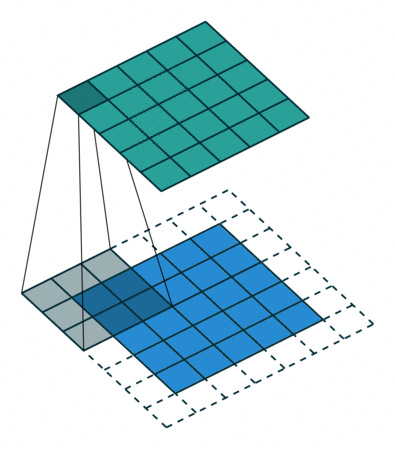

The difference between a convolution layer and a fully connected layer can be described as follows: In a convolutional layer neurons only receive input from a subarea of the previous layer. In a fully connected layer each neuron receives input from *every* element of the previous layer. The image below gives you an overview of the process (source).

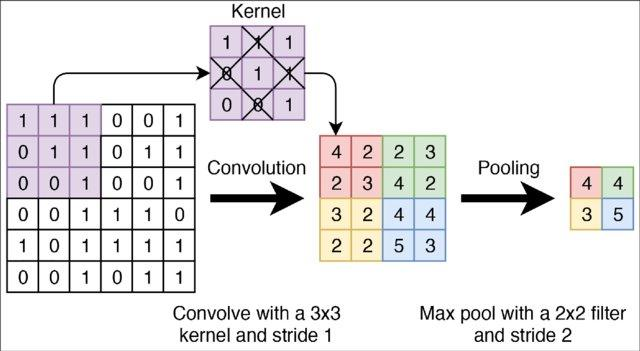

### Application 1 - Revisiting the handwritten number recognition again

% Load up the data
D = readtable('./datasets/MNIST-train.csv');
% use only 10% of data for training
part = cvpartition(D.label,"HoldOut", 0.9, "Stratify", true);
% limit data for training
d = D(part.training,:);
% data for testing (limit to 1k entries)
t = D(part.test,:);
t = t(1:1000,:);

We will be using the same data as before, however, we will need to make some modifications to how the data is represented. Up to now, we just used the information of the pixels, without taking into account the information on neigbouring pixels. We will reshape the data in tabular form into a (28, 28, 1, 4200) sized tensor. The first two values are the image size, the third value is the number of channels in our image (only one as it is a grayscale image). The value 4200 is the number of training examples. For larger volumes of data (that don't necessarily fit in memory), you should use a datastore.

% important to know that Matlab is column major, hence the transpose
X_train = reshape(d{:,2:end}', 28,28, 1, []);
Y = d{:,1}; % contains the actual number
Y_train = categorical(Y); % contains the category
X_val = reshape(t{:,2:end}', 28,28, 1, []);
Y_val = categorical(t{:,1});

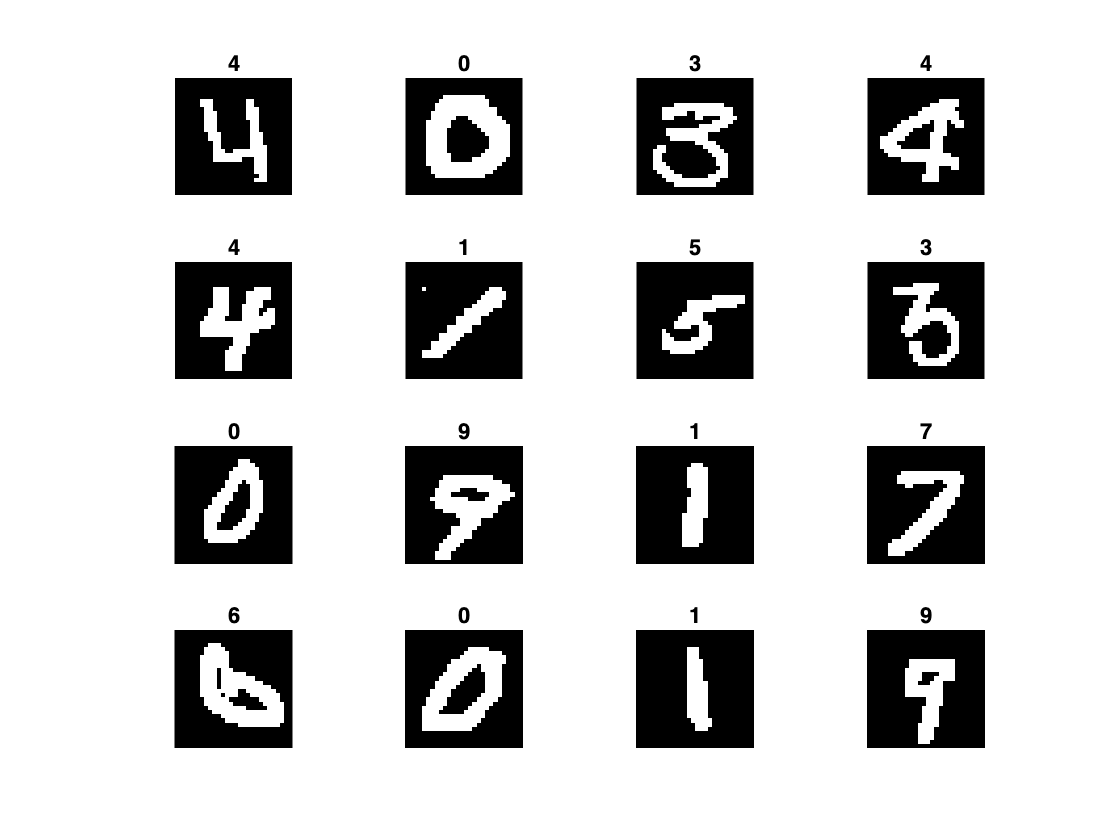

% Quick reference to verify transformation worked as intended
figure()
for i = 1:16
    subplot(4,4,i)
    imshow(X_train(:,:,1,i)');  
    title(sprintf('%i', Y(i))) 
end

Now that we have our data in an proper format, all we need to do is build and train the network. Note that you can also use the Deep Network Designer toolbox to assist you with this.

layers = [
    % input layer (single channel)
    imageInputLayer([28 28 1],"Name","Grayscale input")
    % convolution layer, 16 filters of size 3x3 filter size
    convolution2dLayer(3,16,"Name","conv_1_3x3")
    % normalize a mini-batch of data across all observations for each channel independently
    batchNormalizationLayer
    % REctified Linear Unit (ReLU) layer
    reluLayer("Name","relu_1")
    % pooling layer
    maxPooling2dLayer(2,"Name","maxpool_1","Stride",2)
    % another convolution layer, 32 filters of size 3x3 filter size
    convolution2dLayer(3,32,"Name","conv_2_3x3")
    % normalize a mini-batch of data across all observations for each channel independently
    batchNormalizationLayer
    % another ReLU layer
    reluLayer("Name","relu_2")
    % another pooling layer
    maxPooling2dLayer(2,"Name","maxpool_2","Stride",2)
    % fully connected
    fullyConnectedLayer(10,"Name","fc")
    % classification part
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

option = trainingOptions('adam',"Plots","none","MiniBatchSize",128,...
    "Shuffle","every-epoch", "ValidationData",{X_val, Y_val},"Verbose",false);
[net, info] = trainNetwork(X_train,Y_train, layers, option);

% overview of our network
analyzeNetwork(net)

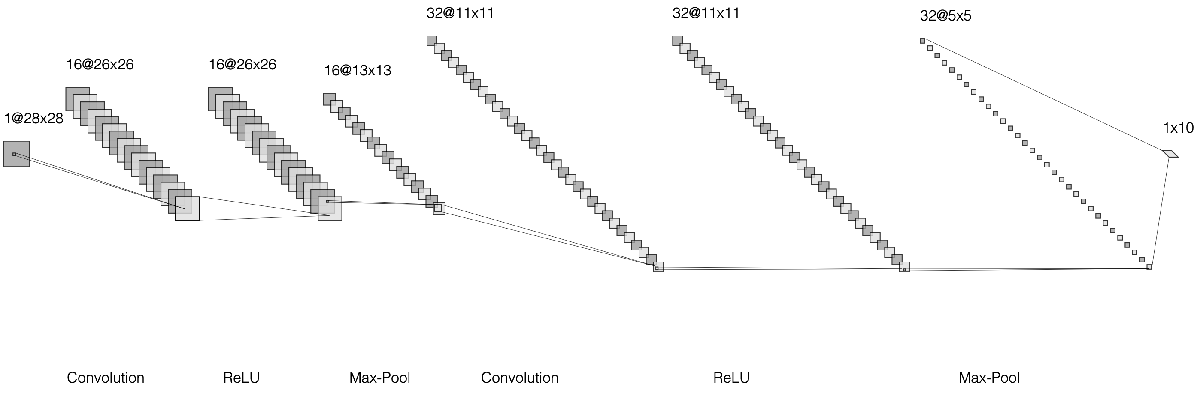

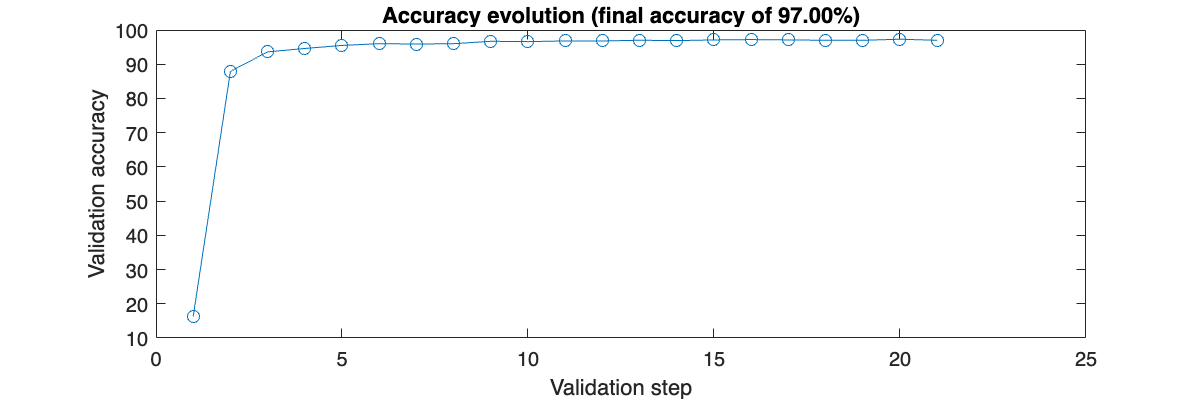

% Small illustration
figure("Position",[0 0 600 200])
plot(info.ValidationAccuracy(~isnan(info.ValidationAccuracy)),'-o');
xlabel('Validation step');
ylabel("Validation accuracy");
title(sprintf("Accuracy evolution (final accuracy of %1.2f%%)", info.ValidationAccuracy(end)));

#### Understanding and interpreting the results

We have trained a model that performs reasonably well. in order to better understand its inner workings, we will look into the effect of the filters by analyzing the results of each layer.

% overview of the layers
net.Layers

ans =   12×1 Layer array with layers:

     1   'Grayscale input'   Image Input             28×28×1 images with 'zerocenter' normalization
     2   'conv_1_3x3'        2-D Convolution         16 3×3×1 convolutions with stride [1  1] and padding [0  0  0  0]
     3   'batchnorm_1'       Batch Normalization     Batch normalization with 16 channels
     4   'relu_1'            ReLU                    ReLU
     5   'maxpool_1'         2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv_2_3x3'        2-D Convolution         32 3×3×16 convolutions with stride [1  1] and padding [0  0  0  0]
     7   'batchnorm_2'       Batch Normalization     Batch normalization with 32 channels
     8   'relu_2'            ReLU                    ReLU
     9   'maxpool_2'         2-D Max Pooling         2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   'fc'          

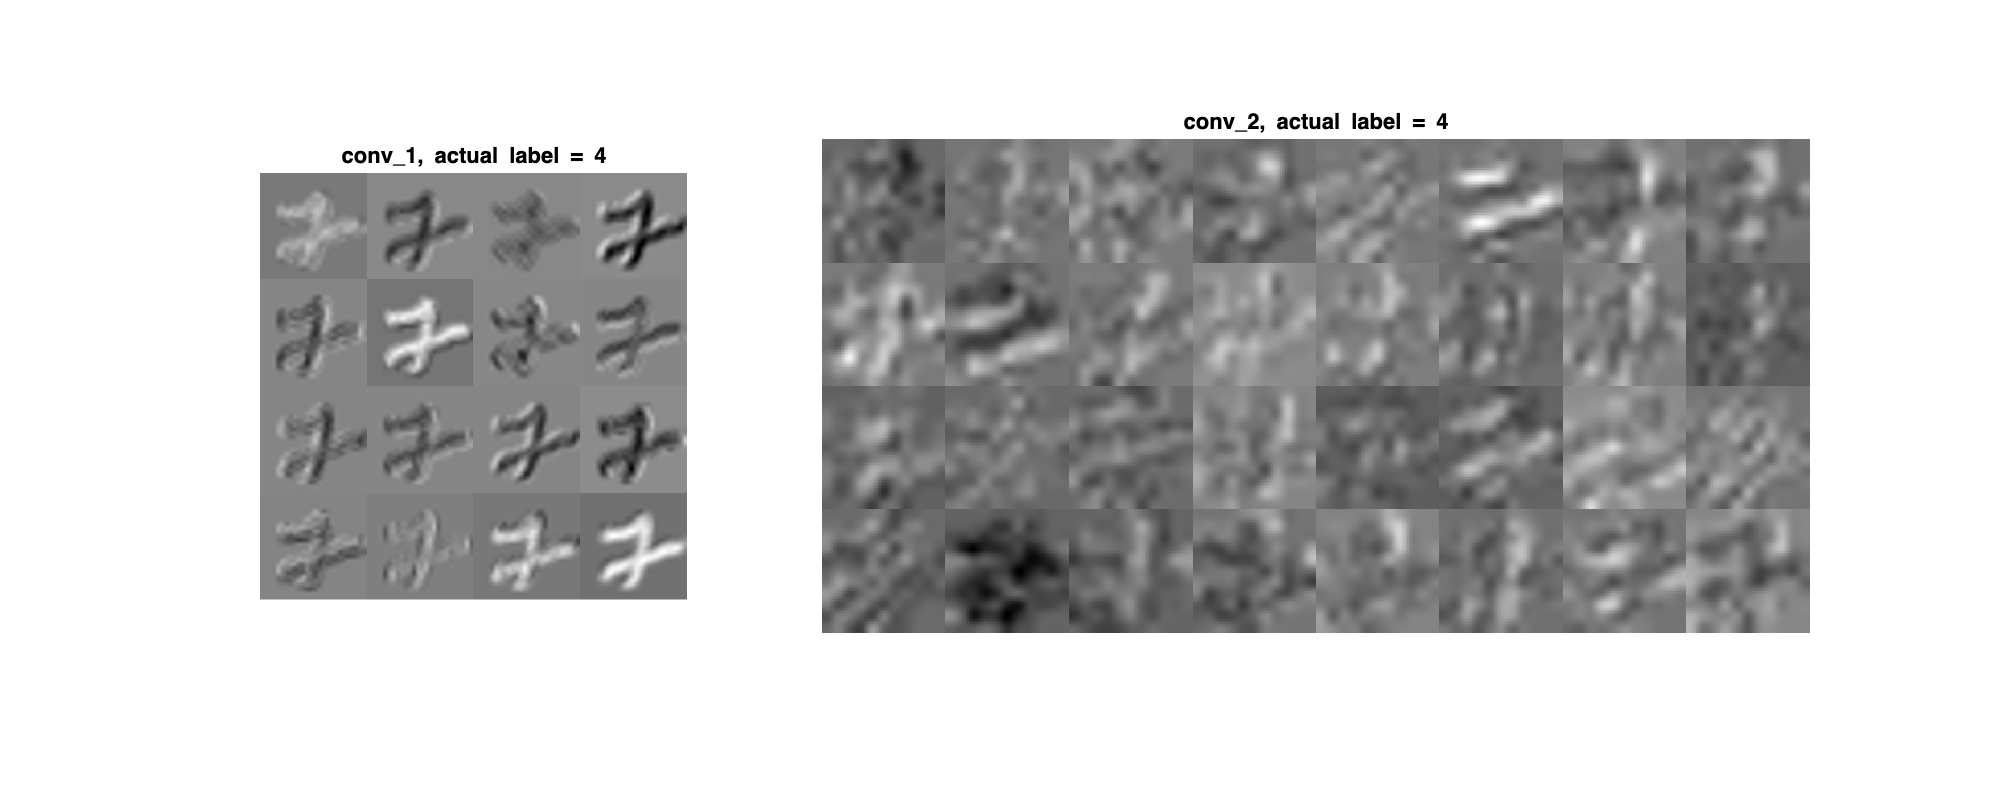

% select a specific image
n = 5; % img number
img = X_train(:,:,:,n);
actual_label = Y(n);
% run it through the network
conv1_res = activations(net,img,'conv_1_3x3'); % 26x26x16 size => why?
conv2_res = activations(net,img,'conv_2_3x3'); % 11x11x32 size => why?
% resize for plotting
sz1 = size(conv1_res);
conv1_res = reshape(conv1_res,[sz1(1) sz1(2) 1 sz1(3)]);
sz2 = size(conv2_res);
conv2_res = reshape(conv2_res,[sz2(1) sz2(2) 1 sz2(3)]);
% normalize for plotting (map to [0,1]
conv1_res = (conv1_res - min(min(min(conv1_res)))) / (max(max(max(conv1_res))) - min(min(min(conv1_res))));
conv2_res = (conv2_res - min(min(min(conv2_res)))) / (max(max(max(conv2_res))) - min(min(min(conv2_res))));
% actual plot
figure("Position",[0 0 1000 400])
subplot(1,3,1)
I1 = imtile(conv1_res,'GridSize',[4 4],'ThumbnailSize', [100 100]);
imshow(I1);
title(sprintf("conv\\_1, actual label = %i", actual_label))
subplot(1,3,2:3)
I2 = imtile(conv2_res,'GridSize',[4 8],'ThumbnailSize', [80 80]);
imshow(I2)
title(sprintf("conv\\_2, actual label = %i", actual_label))

### Task - Improving handwritten number recognition

Now that you have seen an implementation of a CNN for handwriting recognition, try to build a better one for yourself. You can use a form of optimisation similar to what you did in previous sessions. You could experiment with the setting of the different filters. 